# Explore Operating Limits with Simulations

In addition to actuation sizing, simulation studies can aid in exploring the limits of equipment and allow for control strategies to be optimized for common scenerios. In this example, drive speed and top drive load are varied to see distance required to stop a load.

mdl = 'drawWorks_forOpt';

## Region of Operation to Simulate

Initialize vectors to sweep operation through in the simulation.

spdVec = [-1500:50:1500]; spdVec(spdVec == 0) = [];
loadVec = [1 2 3 4:0.1:10.6];

[xVec,yVec] = meshgrid(spdVec,loadVec);
inputVec = [xVec(:) yVec(:)];
numSim = size(inputVec,1);

% With Neural Network Toolbox, can use "combvec" function
% Allows up to N inputs (meshgrid only allows up to 3D)
% inputVec = combvec(spdVec,loadVec)';

## Setup Simulation Input to leverage Parallel Simulations

The Simulink.SimulationInput class can be used to setup varying inputs/parameters for parallel simulations. We vary the motor speed and top drive loads in this study using the setVariable method.

for i = 1:numSim
    in(i) = Simulink.SimulationInput(mdl);
    in(i) = in(i).setVariable('spdCmd',inputVec(i,1));
    in(i) = in(i).setVariable('loadScale',inputVec(i,2));
end
in(1)

ans =   SimulationInput with properties:

          ModelName: 'drawWorks_forOpt'
       InitialState: [0×0 Simulink.op.ModelOperatingPoint]
      ExternalInput: []
    ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
    BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
          Variables: [1×2 Simulink.Simulation.Variable]
          PreSimFcn: []
         PostSimFcn: []
         UserString: ''


## Parallel Simulations using "parsim" command

The parsim command distributes the parallel simulations created with the Simulink.SimulationInput class. These simulations can be distributed locally on multiple cores of a processor or even to a distributed computing system.

warning('off','physmod:simscape:engine:core:advancer_errors:fallback_solve');
warning('off','physmod:common:gl:sli:rtp:InvalidNonValueReference');
out = sim(in, 'ShowSimulationManager', 'on','UseFastRestart',true,'ShowProgress','off');

## View Results

The height required to stop was saved in every simulation. We can plot this compared to all the input values.

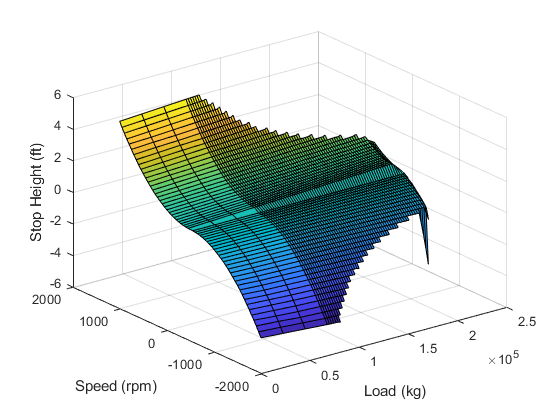

stopVec = [];
for i = 1:numel(out)
    if strcmp(out(i).ErrorMessage,'Simulation aborted') || out(i).yout{1}.Values.Data(end) == 0
        if in(i).Variables(1).Value >= 0
            stopVec = [stopVec; inf];
        else
            stopVec = [stopVec; inf];
        end
        
    else
        stopVec = [stopVec; out(i).yout{1}.Values.Data(end)];
    end
end

loadIn = loadVec*m_drillstring + m_topdrive;

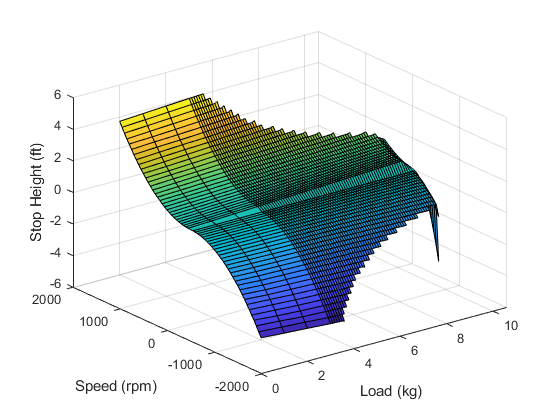

distIn = reshape(stopVec,numel(loadVec),numel(spdVec))';
spdLimitOut = spdVec;
save DrawworksLimitData.mat loadIn distIn spdLimitOut;

surf(loadIn,spdLimitOut,distIn);
xlabel('Load (kg)');
ylabel('Speed (rpm)');
zlabel('Stop Height (ft)');